load run_glm_old.mat; % before PVAF & 'ball' model
model_name={'position','kinematics','hand','eye'};
criteria_name=fieldnames(infoCrit_model_vis{1,1}); % aic bic aicc caic hqc

id_criteria=2;
if id_criteria==0 % log likelihood
    criteria_vis=LL_model_vis;
    criteria_occ=LL_model_occ;
else
    criteria_vis=cellfun(@(x)x.([criteria_name{id_criteria}]),infoCrit_model_vis);
    criteria_occ=cellfun(@(x)x.([criteria_name{id_criteria}]),infoCrit_model_occ);
end

% clustergram?

%% VISIBLE

% VIS: main plot
id_group=[1 2 6 3 7 4 8 5 9]; % full -+pos -+kinematics -+hand -+eye
LL_model_vis2=criteria_vis(:,id_group); % [#neuron x model]
n_neuron=size(criteria_vis,1);

% find best model for inclusive vs exclusive
dLLwo=LL_model_vis2(:,1)-LL_model_vis2(:,2:2:end); % >0
LLw=LL_model_vis2(:,3:2:end); % <0 find max
nLLw=-LLw; % >0 find min

% normalize to [0 1] for [worst best] model
pLLwo=(dLLwo-min(dLLwo,[],2))./(max(dLLwo,[],2)-min(dLLwo,[],2));
pLLw=(LLw-min(LLw,[],2))./(max(LLw,[],2)-min(LLw,[],2));

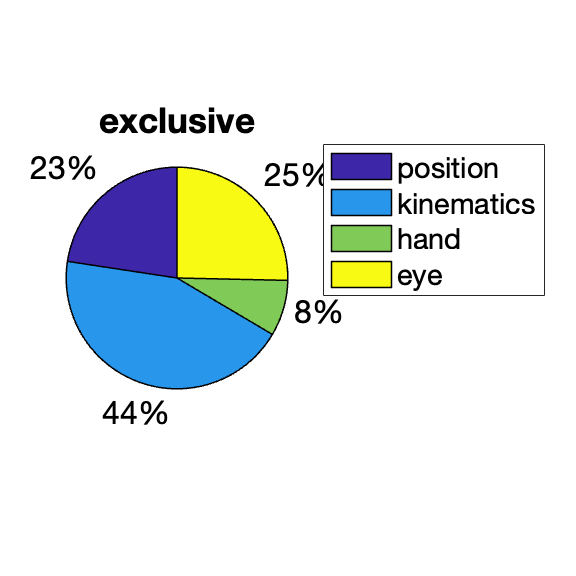

% pie chart
[~,bestModel_wo]=max(dLLwo,[],2);
[~,bestModel_w]=max(LLw,[],2);

[n_wo,~]=histcounts(bestModel_wo,'BinMethod','integers');
pie(n_wo);
title('exclusive');
legend(model_name,'Location',"bestoutside");
applytofig4keynote;

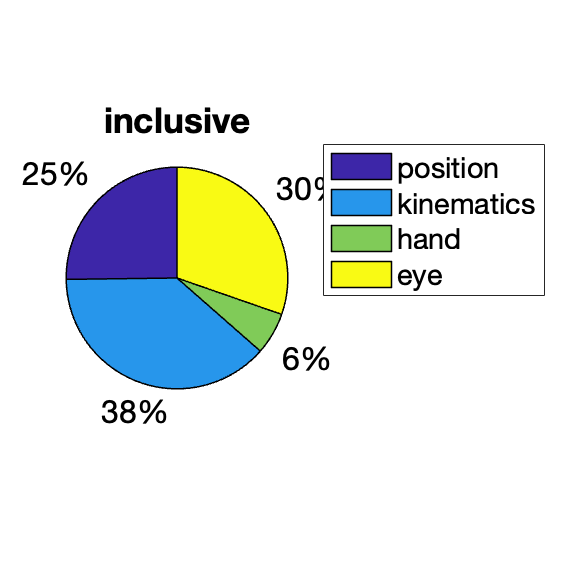


[n_w,~]=histcounts(bestModel_w,'BinMethod','integers');
pie(n_w);
title('inclusive');
legend(model_name,'Location',"bestoutside");
applytofig4keynote;


disp(mean(bestModel_wo==bestModel_w)); % 70% consistent

    0.6903



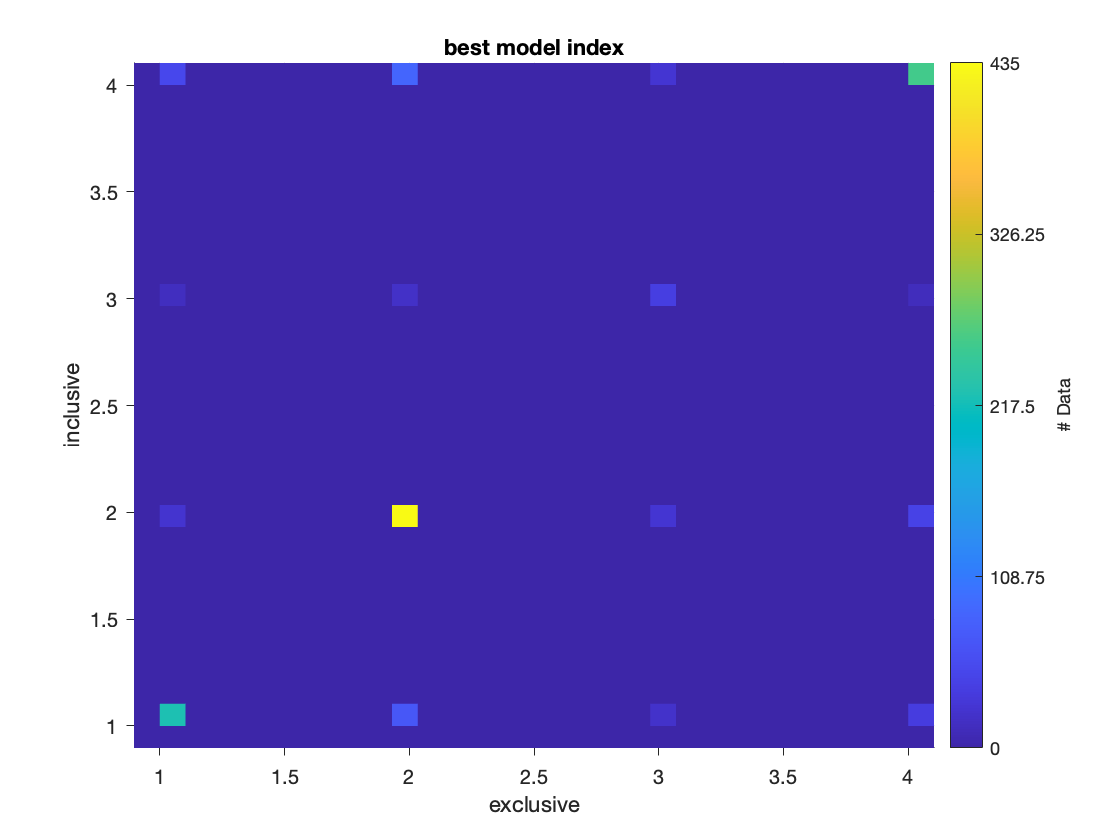

figure;
plotCmap(bestModel_wo,bestModel_w,0);
title('best model index');
xlabel('exclusive')
ylabel('inclusive')

%% OCCLUSION

% OCC: main plot
id_group=[1 2 6 3 7 4 8 5 9]; % full -+pos -+kinematics -+hand -+eye
LL_model_occ2=criteria_occ(:,id_group); % [#neuron x model]
n_neuron=size(criteria_occ,1);

% find best model for inclusive vs exclusive
dLLwo=LL_model_occ2(:,1)-LL_model_occ2(:,2:2:end); % >0
LLw=LL_model_occ2(:,3:2:end); % <0 find max
nLLw=-LLw; % >0 find min

% normalize to [0 1] for [worst best] model
pLLwo=(dLLwo-min(dLLwo,[],2))./(max(dLLwo,[],2)-min(dLLwo,[],2));
pLLw=(LLw-min(LLw,[],2))./(max(LLw,[],2)-min(LLw,[],2));

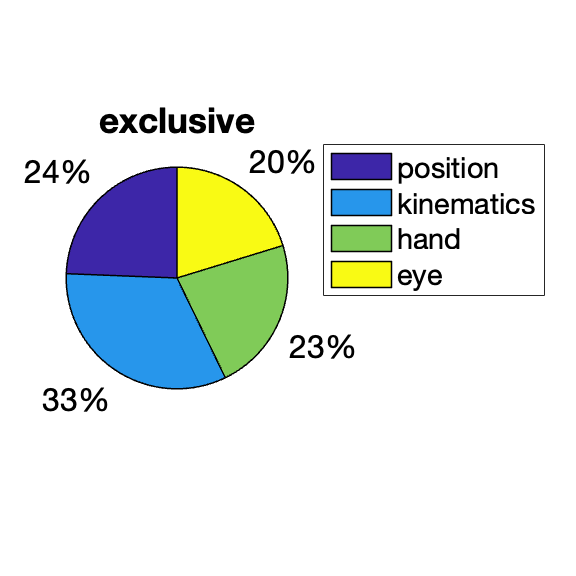

% pie chart
[~,bestModel_wo]=max(dLLwo,[],2);
[~,bestModel_w]=max(LLw,[],2);

[n_wo,~]=histcounts(bestModel_wo,'BinMethod','integers');
pie(n_wo);
title('exclusive');
legend(model_name,'Location',"bestoutside");
applytofig4keynote;

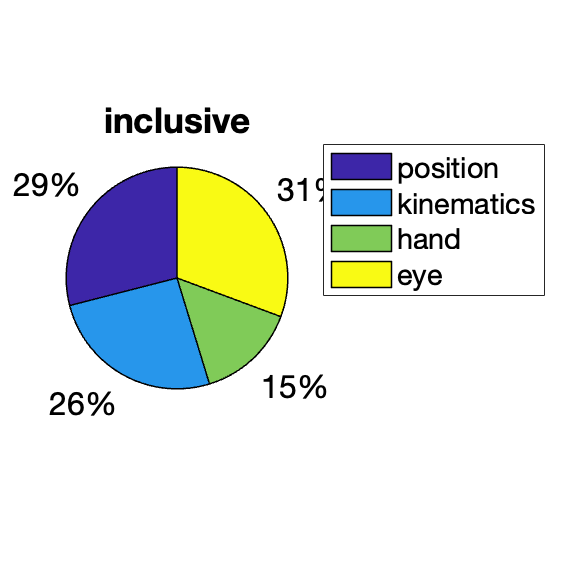


[n_w,~]=histcounts(bestModel_w,'BinMethod','integers');
pie(n_w);
title('inclusive');
legend(model_name,'Location',"bestoutside");
applytofig4keynote;


disp(mean(bestModel_wo==bestModel_w)); % 70% consistent

    0.6106



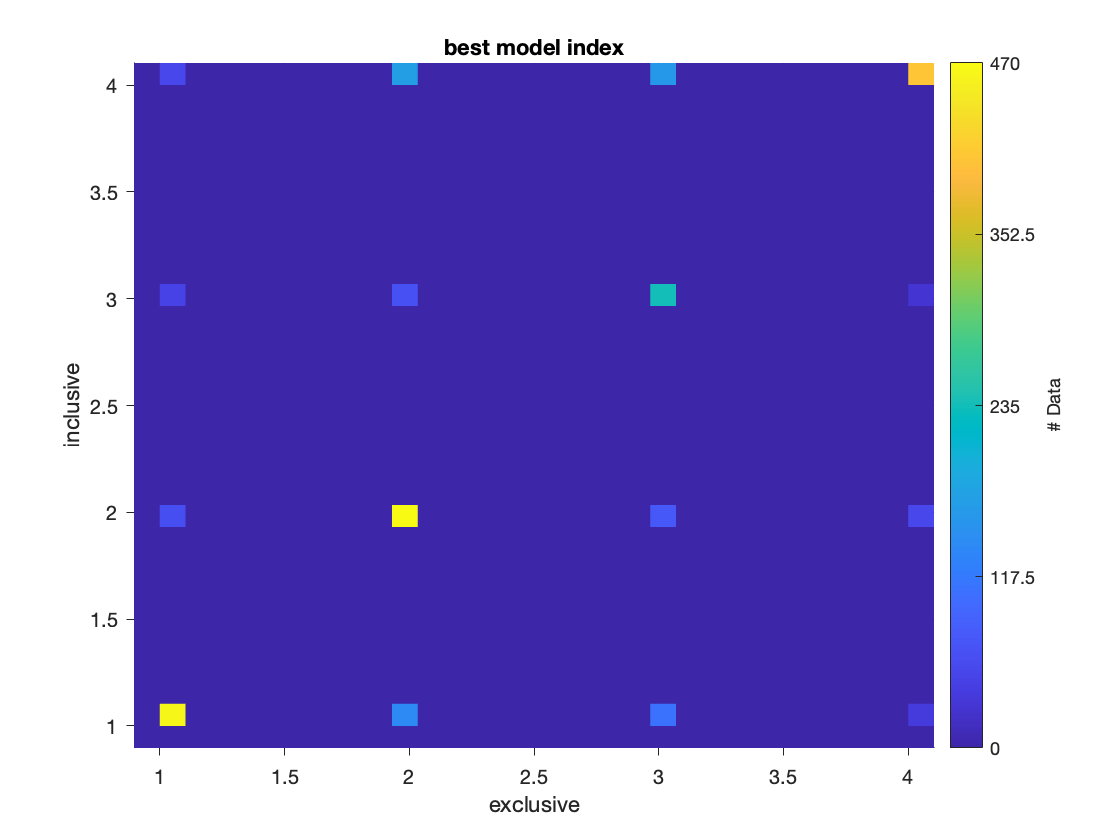

figure;
plotCmap(bestModel_wo,bestModel_w,0);
title('best model index');
xlabel('exclusive')
ylabel('inclusive')

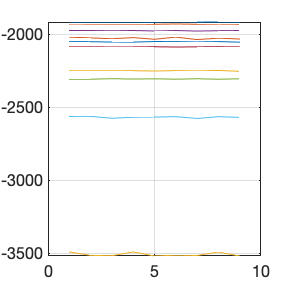

% % example
% figure; plot(LL_model_vis2(randi(n_neuron,10,1),:)');applytofig4keynote;
% grid on;

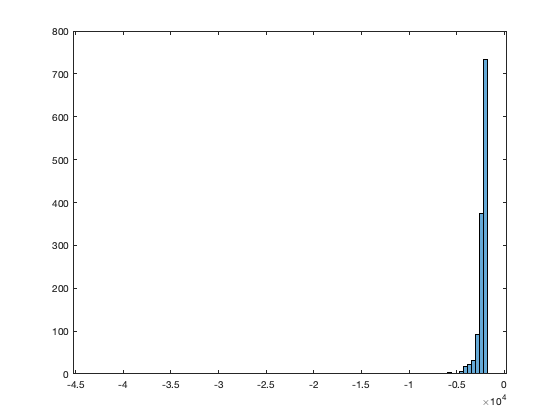

% figure; histogram(LL_model_vis2(:,1),100)

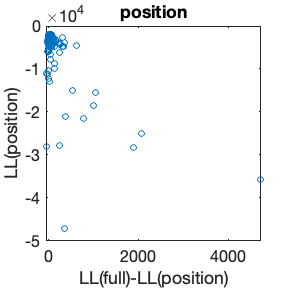

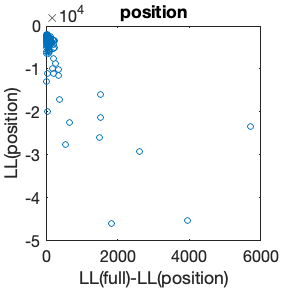

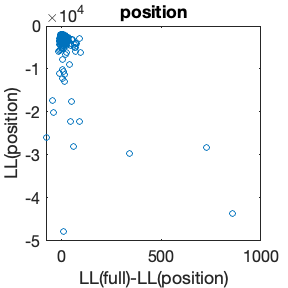

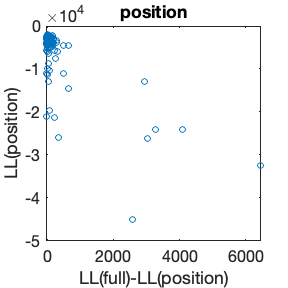

% inspect full-factor vs +factor
i_model=1;
for iFactor=2:2:8 % pos kinem hand eye
    figure;
    dLLwo_tmp=LL_model_vis2(:,1)-LL_model_vis2(:,iFactor);
    nLLw_tmp=-LL_model_vis2(:,iFactor+1);
    plot(dLLwo_tmp,nLLw_tmp,'o');
    title(model_name{i_model});
    xlabel(['LL(full)-LL(' model_name{i_model} ')']);
    ylabel(['LL(' model_name{i_model} ')']);
    plotIdentity(gca)
    applytofig4keynote;
    set(gca,'xscale','log','yscale','log')
end

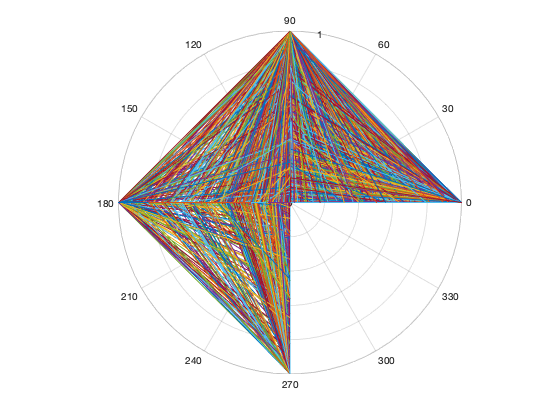

% only inclusive models: polarplot, plotmatrix
% note kinematics has 4 variables; eye has 6; rest has only two

polarplot(0:(pi/2):(pi*3/2),pLLwo')

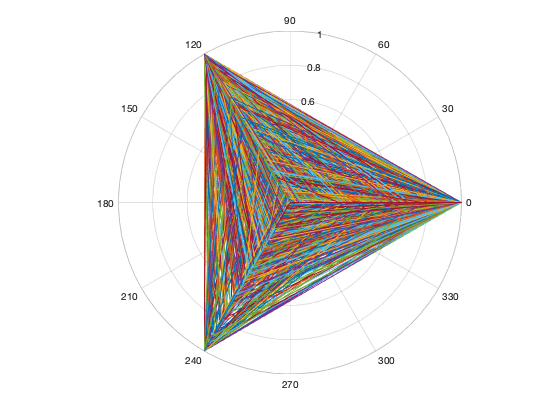


polarplot(0:(pi/2):(pi*3/2),pLLw')

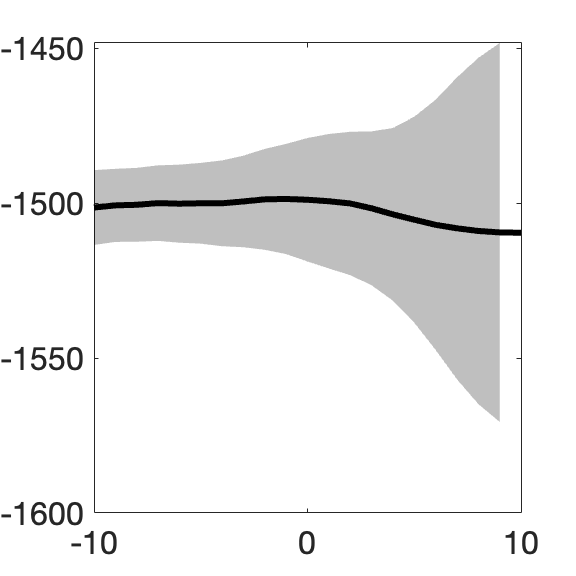

% %% conclusion: best delay doesn't exist across cells, all case by case
% % figure; setFigPos(2,1); imagesc(LL_occ); colorbar;
% figure; setFigPos(2,1); shadedErrorBar(p_delay.range_bin,median(LL_occ,1),sem(LL_occ,1),{'-','color','k','linewidth',2},1); applytofig4keynote;

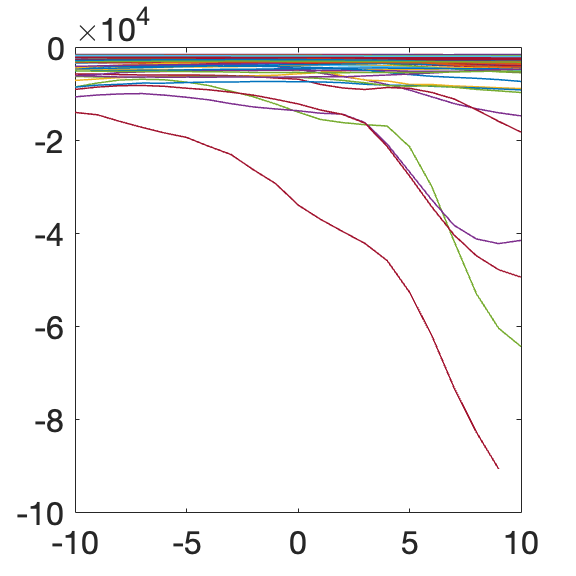

% figure; setFigPos(2,2); plot(p_delay.range_bin,(LL_occ));applytofig4keynote;

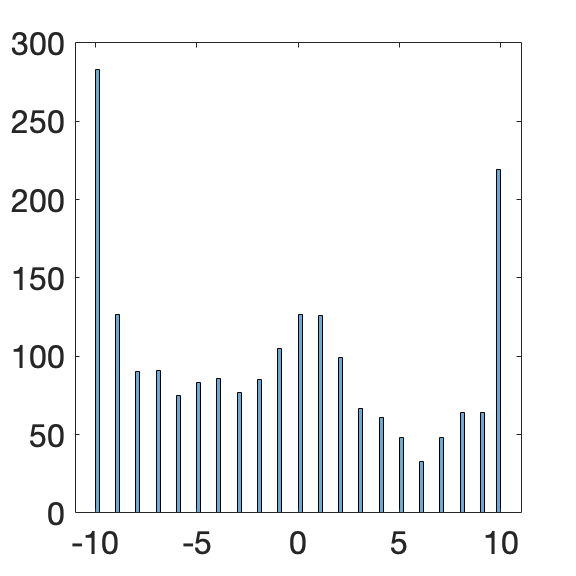

% figure;setFigPos(2,3); histogram(p_delay.range_bin(tMax_occ),100);applytofig4keynote;

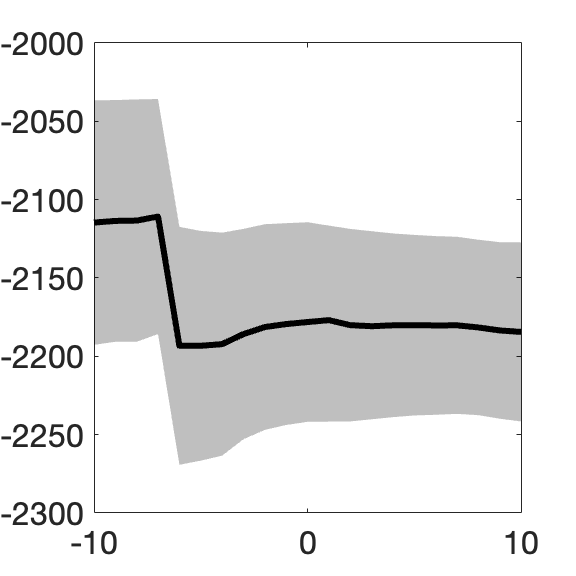

% % figure; setFigPos(1,1); imagesc(LL_vis); colorbar;
% figure; setFigPos(1,1); shadedErrorBar(p_delay.range_bin,median(LL_vis,1),sem(LL_vis,1),{'-','color','k','linewidth',2},1); applytofig4keynote; % 

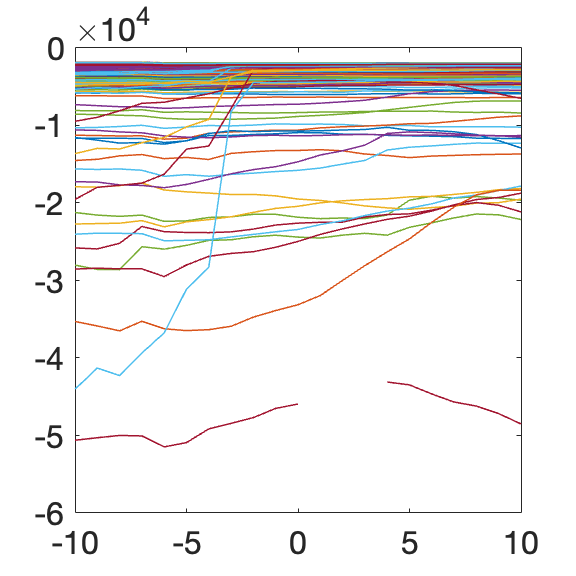

% figure; setFigPos(1,2); plot(p_delay.range_bin,(LL_vis));applytofig4keynote;

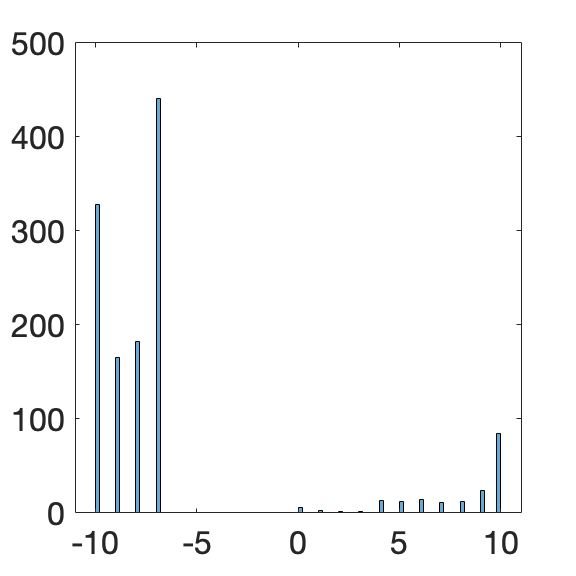

% figure;setFigPos(1,3); histogram(p_delay.range_bin(tMax_vis),100);applytofig4keynote;